# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

** Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

** Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Paula Fernández Sánchez, Luis Ramos Triguero, María Díez Martínez**

**Fecha: 17/11/2026**

# Tema 4. Ejercicio 3. *Local Features*

El objetivo de esta práctica es mostrar el potencial de las denominadas "*Local Features*". Para ello se va a buscar un objeto dentro de una escena utilizando los detectores y descriptores de características locales.

clear all
close all

Step 1) Leer la imagen de referencia que contiene el objeto de interés.

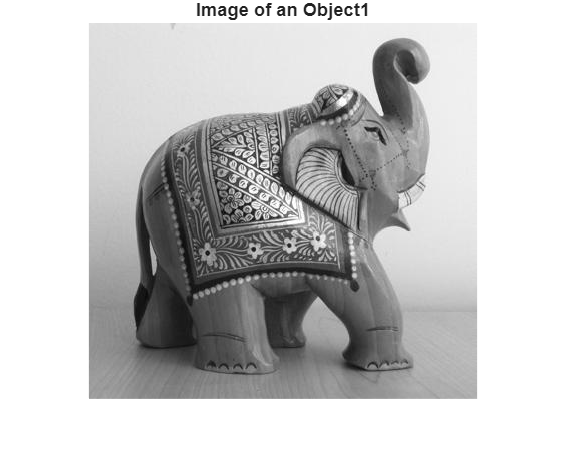

Object1Image = imread('elephant.jpg');
 
figure;
imshow(Object1Image);
title('Image of an Object1');

Se lee la escena que contiene al objeto de interés.

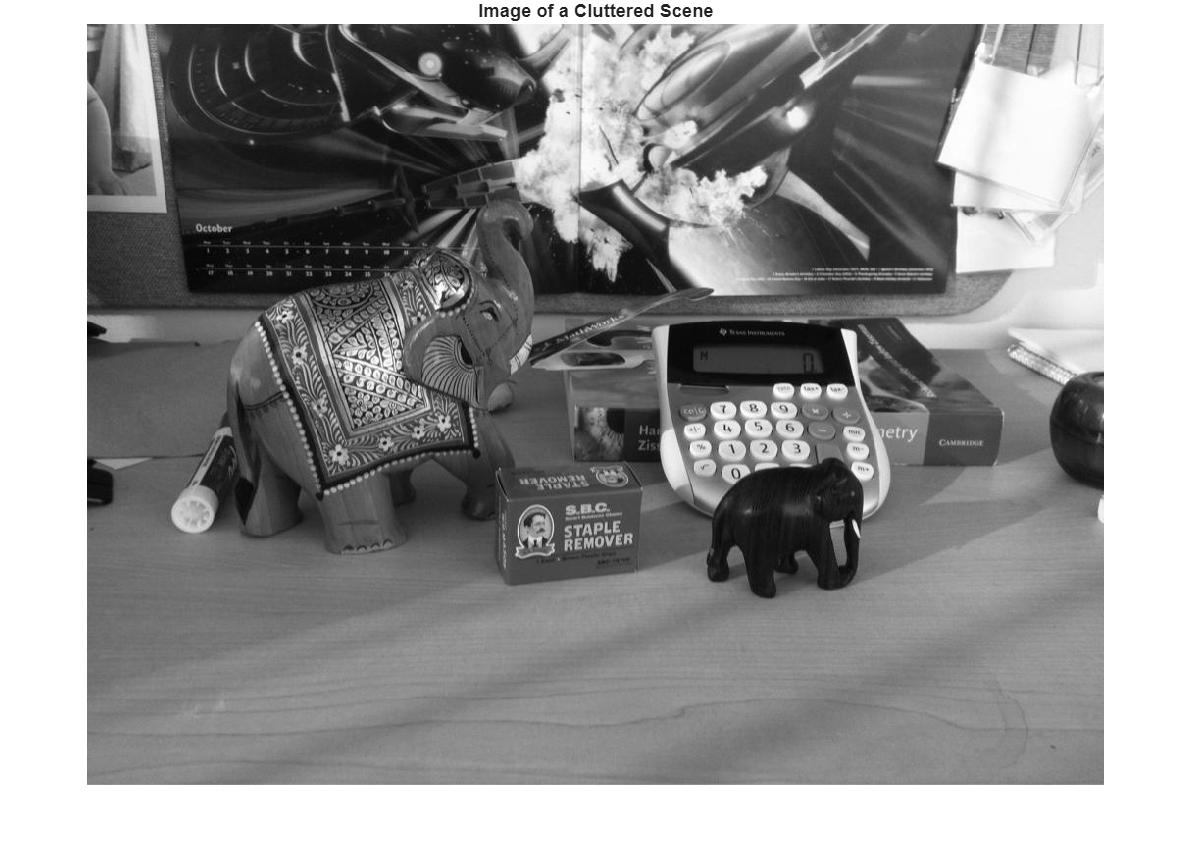

sceneImage = imread('clutteredDesk.jpg');
figure; 
imshow(sceneImage);
title('Image of a Cluttered Scene');

 Step 2) Se detectan las características locales del objeto y de la escena:

% Detect feature points in both images.
Object1Points = detectSURFFeatures(Object1Image);
scenePoints = detectSURFFeatures(sceneImage);

Se visualizan los puntos más fuertes que se encuentran en la imagen del objeto de referencia:

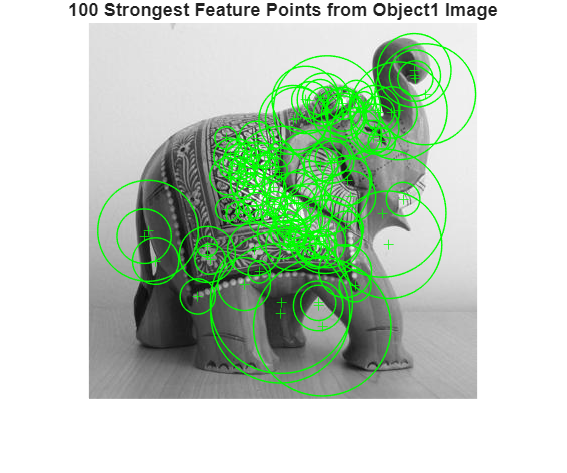

figure; 
imshow(Object1Image);
title('100 Strongest Feature Points from Object1 Image');
hold on;
plot(selectStrongest(Object1Points, 100));

Se visualizan los puntos más fuertes que se encuentran en la imagen de la escena

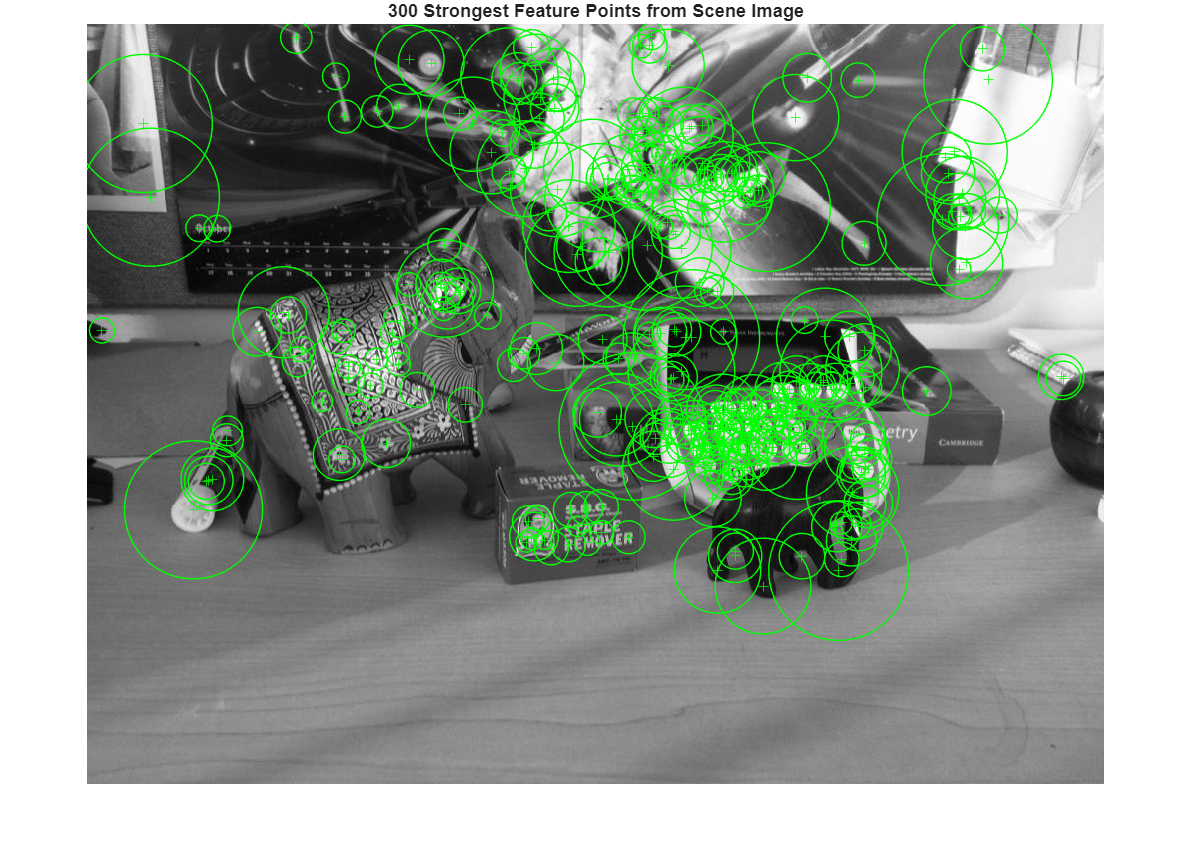

figure; 
imshow(sceneImage);
title('300 Strongest Feature Points from Scene Image');
hold on;
plot(selectStrongest(scenePoints, 300));

Step 3) Se extraen los descriptores de caracterísitcas de ambas imágenes.

[Object1Features, Object1Points] = extractFeatures(Object1Image, Object1Points);
[sceneFeatures, scenePoints] = extractFeatures(sceneImage, scenePoints);

Step 4) Se encuentran las coincidencias (*matches*) y se visualizan.

Object1Pairs = matchFeatures(Object1Features, sceneFeatures, 'MaxRatio', 0.9);
numMatches = size(Object1Pairs,1)

numMatches = 12

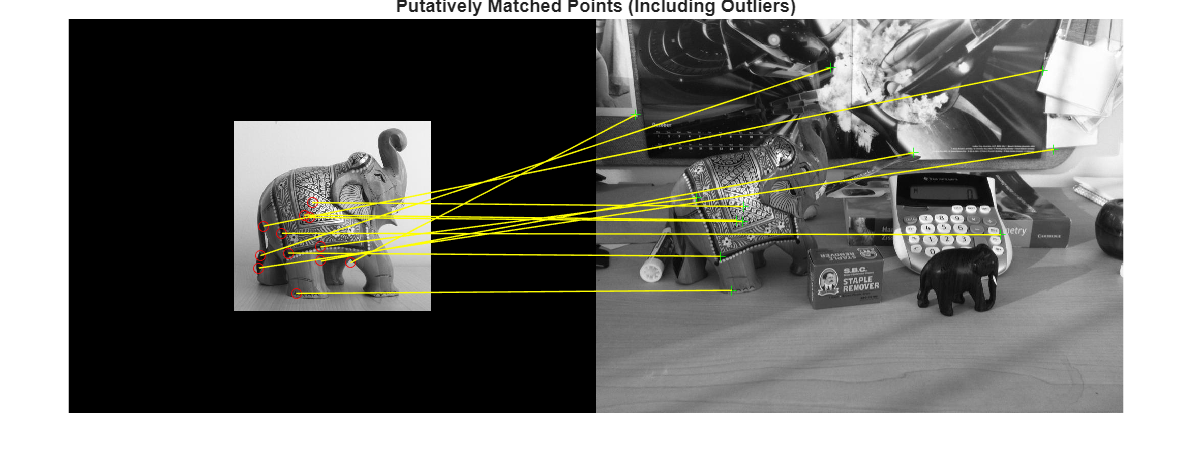

matchedObject1Points = Object1Points(Object1Pairs(:, 1), :);
matchedScenePoints = scenePoints(Object1Pairs(:, 2), :);
figure;
showMatchedFeatures(Object1Image, sceneImage, matchedObject1Points, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

Step 5) Se localiza el objeto en la escena usando las coincidencias. 

`estimateGeometricTransform` calcula la transformación relacionando los puntos coincidentes, a la vez que elimina los valores outliers. Esta transformación nos permite localizar el objeto en la escena.

[tform, inlierObject1Points, inlierScenePoints] = estimateGeometricTransform(matchedObject1Points, matchedScenePoints, 'affine');
numInliers = inlierObject1Points.Count

numInliers = 4

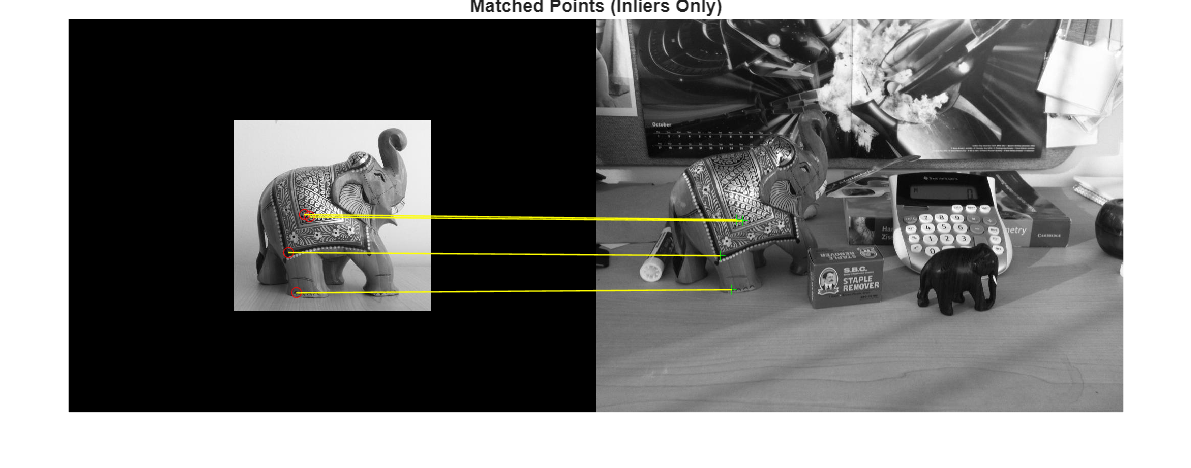

figure;
showMatchedFeatures(Object1Image, sceneImage, inlierObject1Points, inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

Se obtiene el polígono delimitador de la imagen de referencia.

Object1Polygon = [1, 1;...                           % top-left
        size(Object1Image, 2), 1;...                 % top-right
        size(Object1Image, 2), size(Object1Image, 1);... % bottom-right
        1, size(Object1Image, 1);...                 % bottom-left
        1, 1];                   % top-left again to close the polygon 

Se transforma el polígono en el sistema de coordenadas de la imagen de destino. El polígono transformado indica la ubicación del objeto1 en la escena.

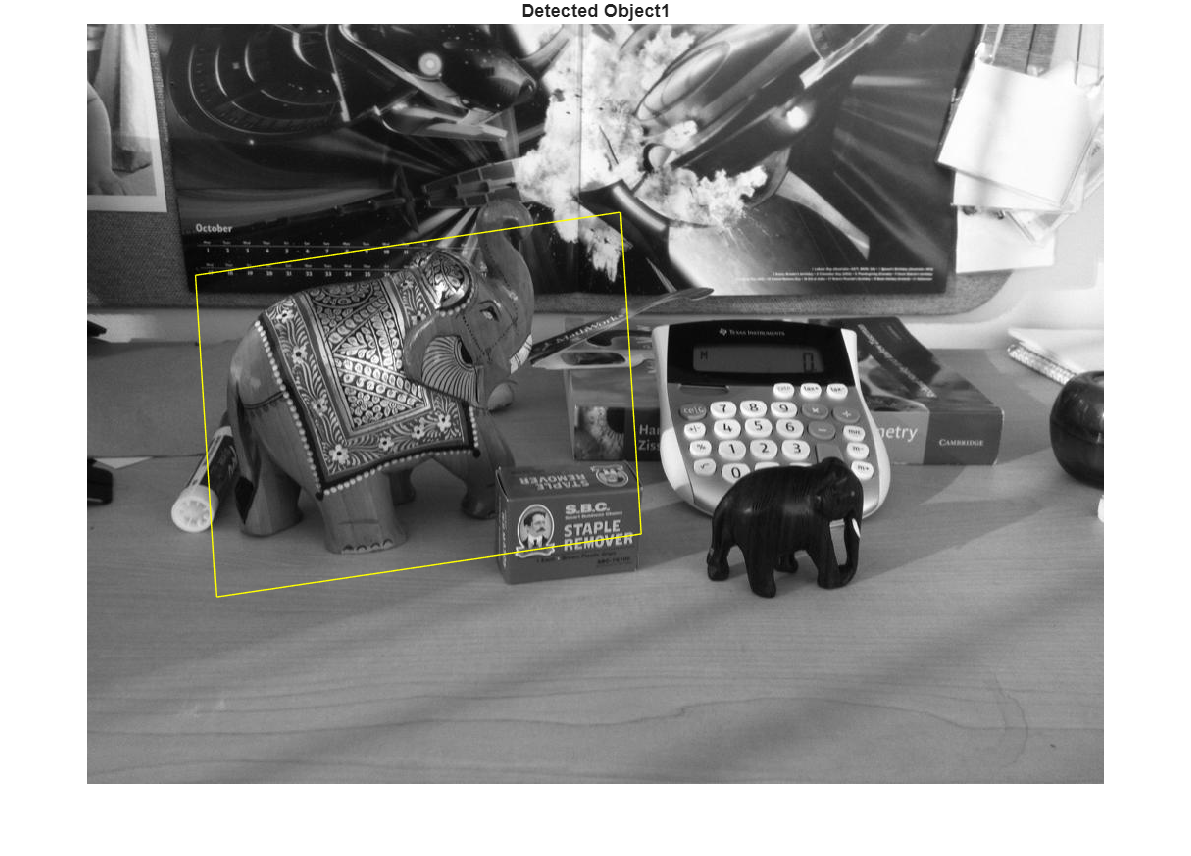

newObject1Polygon = transformPointsForward(tform, Object1Polygon);    

figure;
imshow(sceneImage);
hold on;
line(newObject1Polygon(:, 1), newObject1Polygon(:, 2), 'Color', 'y');
title('Detected Object1');

Se pide:

- Repita el proceso anterior pero buscando otro objeto de la escena, en este caso la caja de la grapadora, cuya imagen es `'stapleRemover.jpg'`. Además utilice el detector y descriptor BRISK ([`detectBRISKFeatures`](https://es.mathworks.com/help/vision/ref/detectbriskfeatures.html)). Compruebe cuántos pares de puntos empareja el algoritmo visualizando la salida de la función **matchFeatures**.

- Añada ruido gaussiano de varianza `0.001` a la imagen `'clutteredDesk.jpg'` y repita el apartado anterior. Compare el número de emparejamientos y de `inliers `con los obtenidos sin ruido. ¿Sigue siendo posible localizar correctamente el objeto?

JUSTIFICACION: Con ruido de varianza 0.001 bajan un poco los emparejamientos y los inliers, pero el objeto se sigue localizando bien porque quedan suficientes puntos buenos.

- Repita el apartado anterior utilizando ruido gaussiano de varianza `0.01`. Compare nuevamente el número de emparejamientos y de `inliers`. ¿Es posible localizar el objeto?

JUSTIFICACION: Con varianza 0.01 el ruido crea muchas esquinas falsas y cambia los descriptores, así que los emparejamientos y sobre todo los inliers bajan mucho. El objeto ya no se localiza bien o directamente no se puede localizar.

- Aplique a la imagen ruidosa alguna técnica de reducción de ruido estudiada previamente y repita el proceso. ¿Mejora el resultado? Justifique la respuesta a partir del número de correspondencias obtenidas y de la localización final del objeto.

JUSTIFICACION: Al filtrar con la media se reduce el ruido y aumentan los emparejamientos y los inliers respecto a la imagen ruidosa, con lo que el objeto vuelve a localizarse mejor. Aun así no se llega a lo que sale sin ruido, porque el filtro también suaviza los bordes y se pierden algunos puntos.

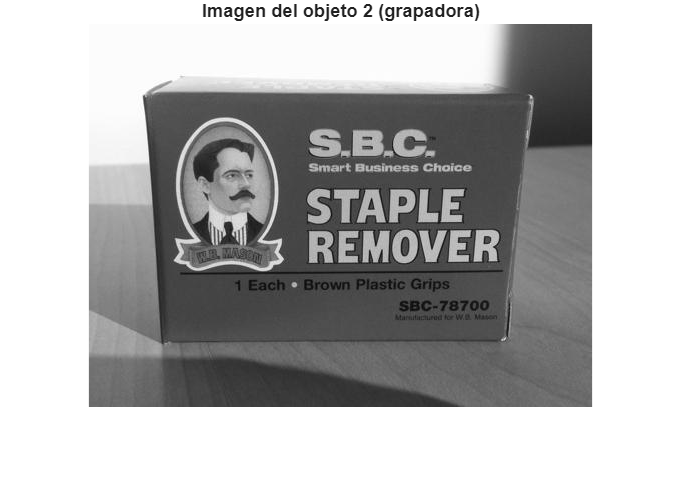

Object2Image = imread('stapleRemover.jpg');
figure;
imshow(Object2Image);
title('Imagen del objeto 2 (grapadora)');

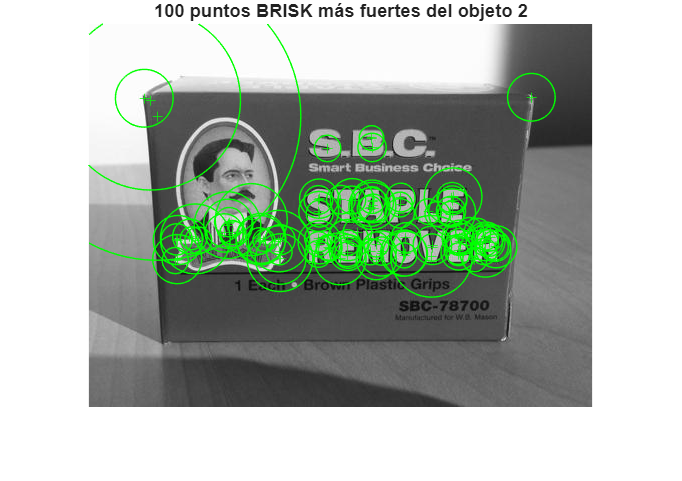


Object2Points = detectBRISKFeatures(Object2Image);
scenePoints2 = detectBRISKFeatures(sceneImage);
figure;
imshow(Object2Image);
title('100 puntos BRISK más fuertes del objeto 2');
hold on;
plot(selectStrongest(Object2Points, 100));


[Object2Features, Object2Points] = extractFeatures(Object2Image, Object2Points);
[sceneFeatures2, scenePoints2] = extractFeatures(sceneImage, scenePoints2);

Object2Pairs = matchFeatures(Object2Features, sceneFeatures2, 'MaxRatio', 0.9);
numMatches2 = size(Object2Pairs,1)

numMatches2 = 11

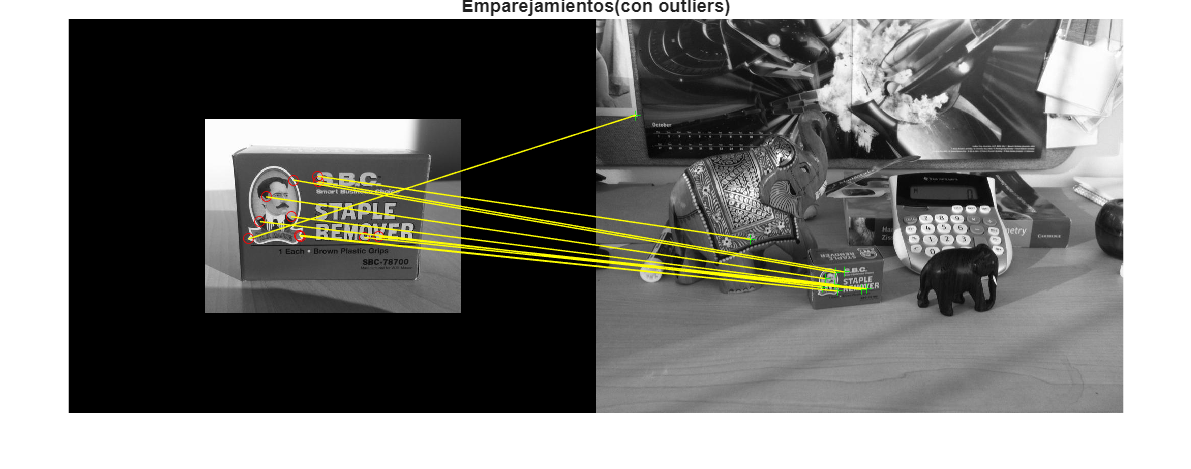

matchedObject2Points = Object2Points(Object2Pairs(:, 1), :);
matchedScenePoints2 = scenePoints2(Object2Pairs(:, 2), :);
figure;
showMatchedFeatures(Object2Image, sceneImage, matchedObject2Points, matchedScenePoints2, 'montage');
title('Emparejamientos(con outliers)');


[tform2, inlierObject2Points, inlierScenePoints2] = estimateGeometricTransform(matchedObject2Points, matchedScenePoints2, 'affine');
numInliers2 = inlierObject2Points.Count

numInliers2 = 9

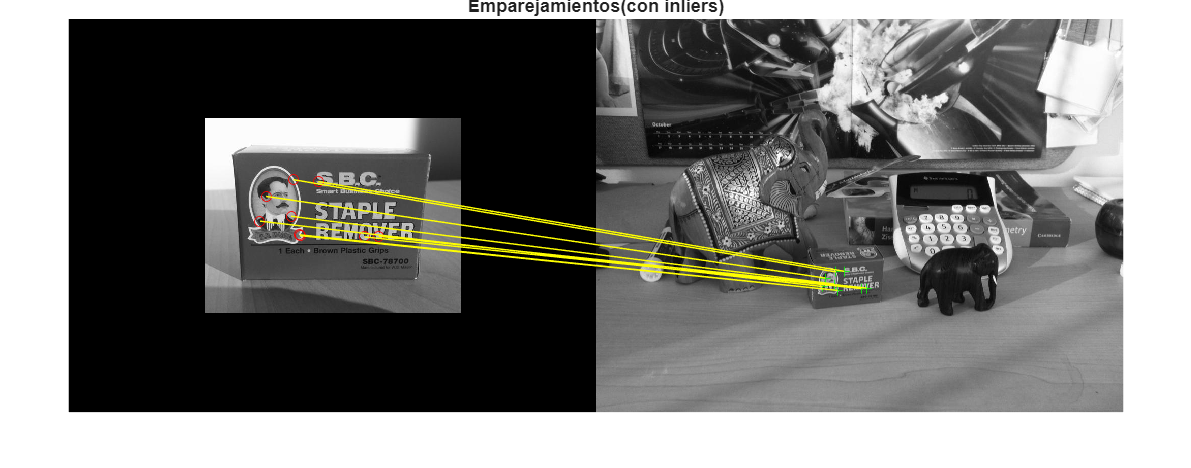

figure;
showMatchedFeatures(Object2Image, sceneImage, inlierObject2Points, inlierScenePoints2, 'montage');
title('Emparejamientos(con inliers)');

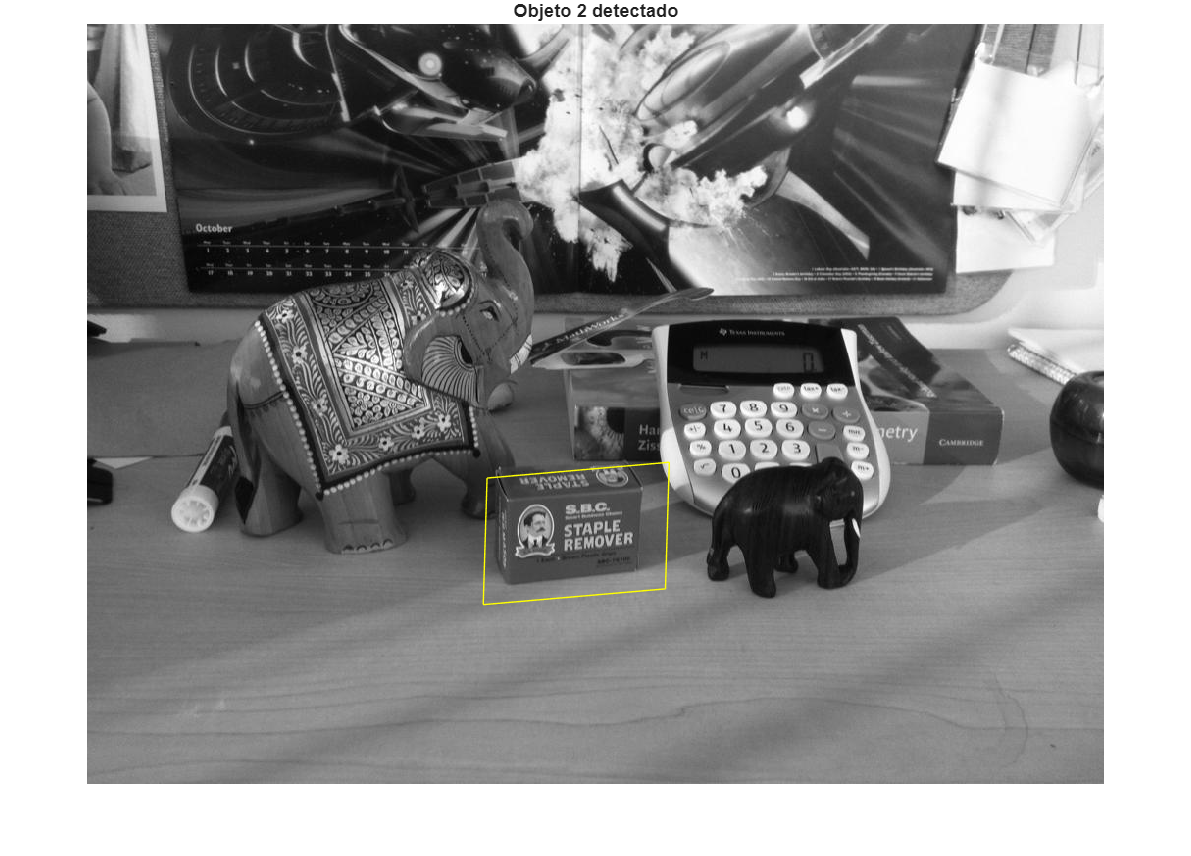


Object2Polygon = [1, 1;...
        size(Object2Image, 2), 1;...
        size(Object2Image, 2), size(Object2Image, 1);...
        1, size(Object2Image, 1);...
        1, 1];
newObject2Polygon = transformPointsForward(tform2, Object2Polygon);
figure;
imshow(sceneImage);
hold on;
line(newObject2Polygon(:, 1), newObject2Polygon(:, 2), 'Color', 'y');
title('Objeto 2 detectado');


sceneRuido1 = imnoise(sceneImage, 'gaussian', 0, 0.001);
scenePointsN = detectBRISKFeatures(sceneRuido1);
[sceneFeaturesN, scenePointsN] = extractFeatures(sceneRuido1, scenePointsN);
PairsN = matchFeatures(Object2Features, sceneFeaturesN, 'MaxRatio', 0.9);
numMatchesN1 = size(PairsN,1)

numMatchesN1 = 6

matchedObject2PointsN = Object2Points(PairsN(:, 1), :);
matchedScenePointsN = scenePointsN(PairsN(:, 2), :);
[tformN, inlierObject2PointsN, inlierScenePointsN] = estimateGeometricTransform(matchedObject2PointsN, matchedScenePointsN, 'affine');
numInliersN1 = inlierObject2PointsN.Count

numInliersN1 = 5

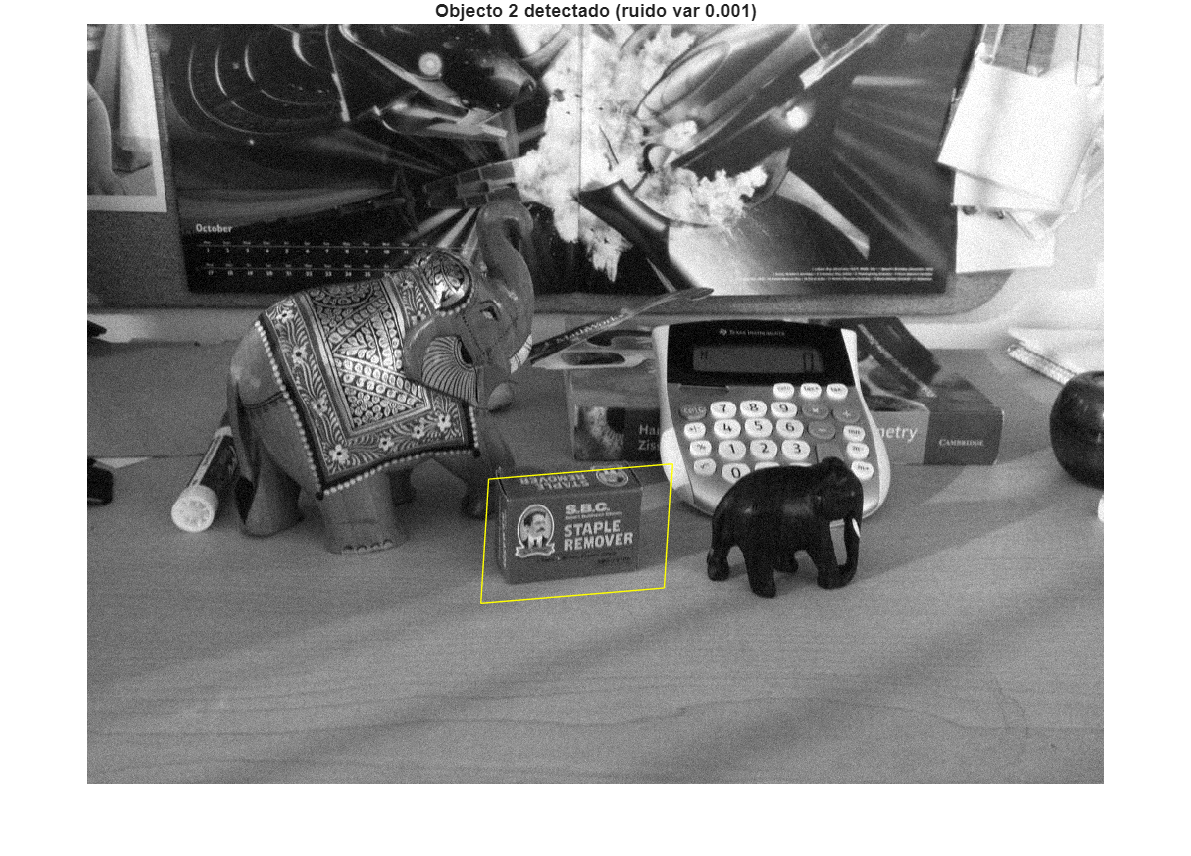

newObject2PolygonN = transformPointsForward(tformN, Object2Polygon);
figure;
imshow(sceneRuido1);
hold on;
line(newObject2PolygonN(:, 1), newObject2PolygonN(:, 2), 'Color', 'y');
title('Objecto 2 detectado (ruido var 0.001)');


sceneRuido2 = imnoise(sceneImage, 'gaussian', 0, 0.01);
scenePointsN = detectBRISKFeatures(sceneRuido2);
[sceneFeaturesN, scenePointsN] = extractFeatures(sceneRuido2, scenePointsN);
PairsN = matchFeatures(Object2Features, sceneFeaturesN, 'MaxRatio', 0.9);
numMatchesN2 = size(PairsN,1)

numMatchesN2 = 4

matchedObject2PointsN = Object2Points(PairsN(:, 1), :);
matchedScenePointsN = scenePointsN(PairsN(:, 2), :);
[tformN, inlierObject2PointsN, inlierScenePointsN] = estimateGeometricTransform(matchedObject2PointsN, matchedScenePointsN, 'affine');
numInliersN2 = inlierObject2PointsN.Count

numInliersN2 = 3

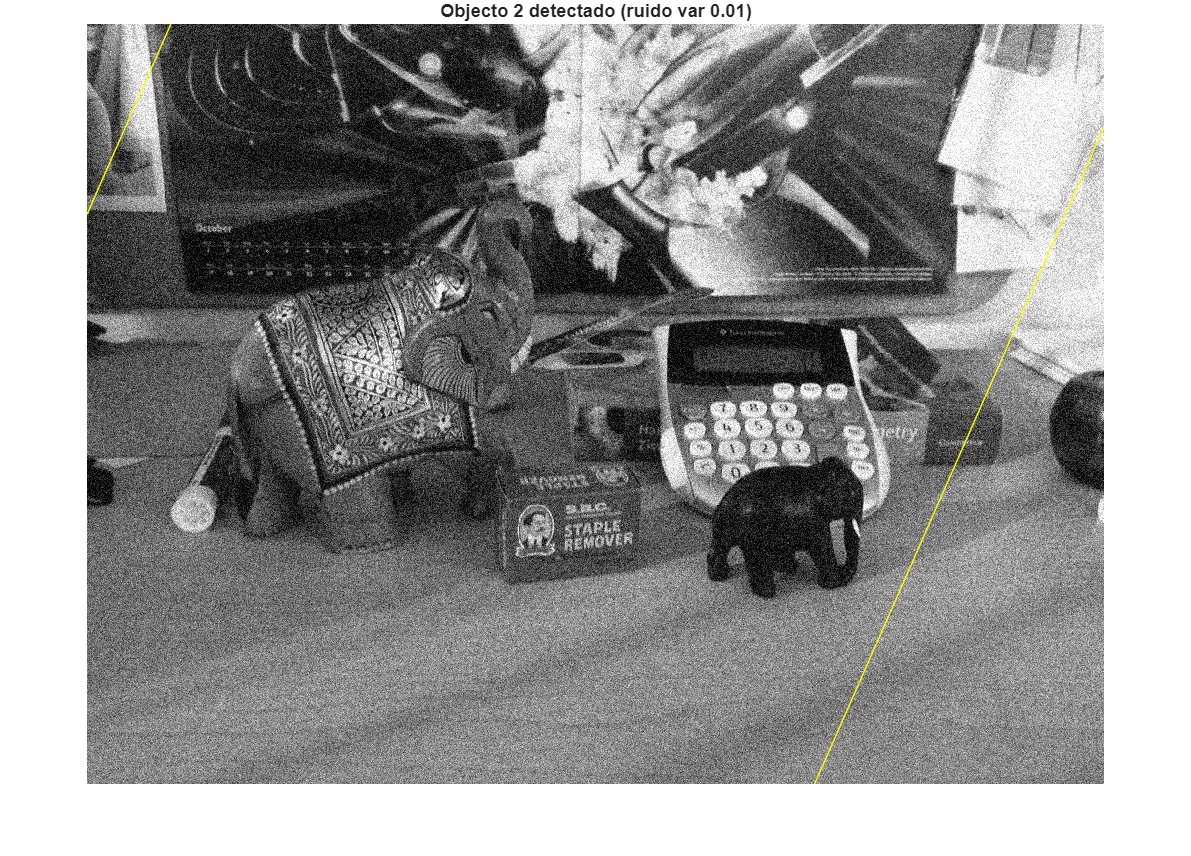

newObject2PolygonN = transformPointsForward(tformN, Object2Polygon);
figure;
imshow(sceneRuido2);
hold on;
line(newObject2PolygonN(:, 1), newObject2PolygonN(:, 2), 'Color', 'y');
title('Objecto 2 detectado (ruido var 0.01)');

h = fspecial('average', 3);
sceneFiltrada = uint8(filter2(h, sceneRuido2));
scenePointsN = detectBRISKFeatures(sceneFiltrada);
[sceneFeaturesN, scenePointsN] = extractFeatures(sceneFiltrada, scenePointsN);
PairsN = matchFeatures(Object2Features, sceneFeaturesN, 'MaxRatio', 0.9);
numMatchesF = size(PairsN,1)

numMatchesF = 6

matchedObject2PointsN = Object2Points(PairsN(:, 1), :);
matchedScenePointsN = scenePointsN(PairsN(:, 2), :);
[tformN, inlierObject2PointsN, inlierScenePointsN] = estimateGeometricTransform(matchedObject2PointsN, matchedScenePointsN, 'affine');
numInliersF = inlierObject2PointsN.Count

numInliersF = 4

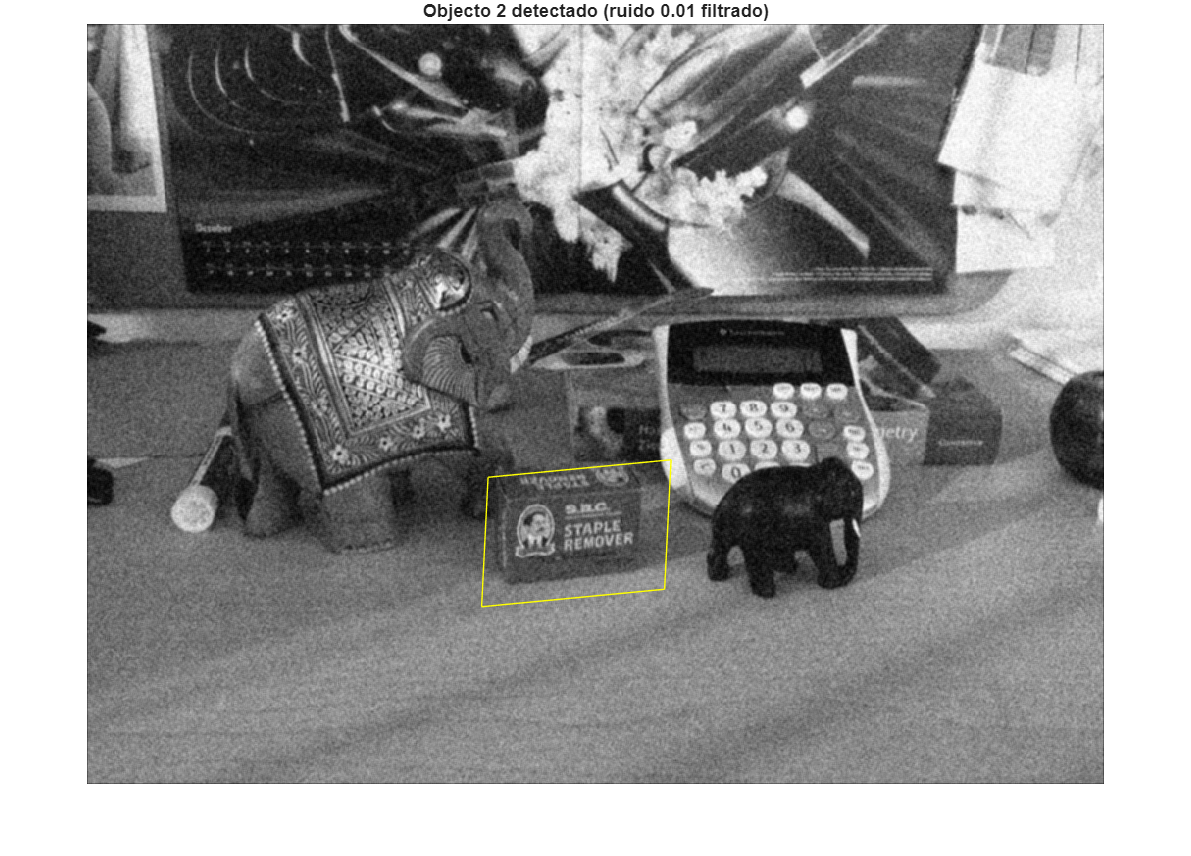

newObject2PolygonN = transformPointsForward(tformN, Object2Polygon);
figure;
imshow(sceneFiltrada);
hold on;
line(newObject2PolygonN(:, 1), newObject2PolygonN(:, 2), 'Color', 'y');
title('Objecto 2 detectado (ruido 0.01 filtrado)');